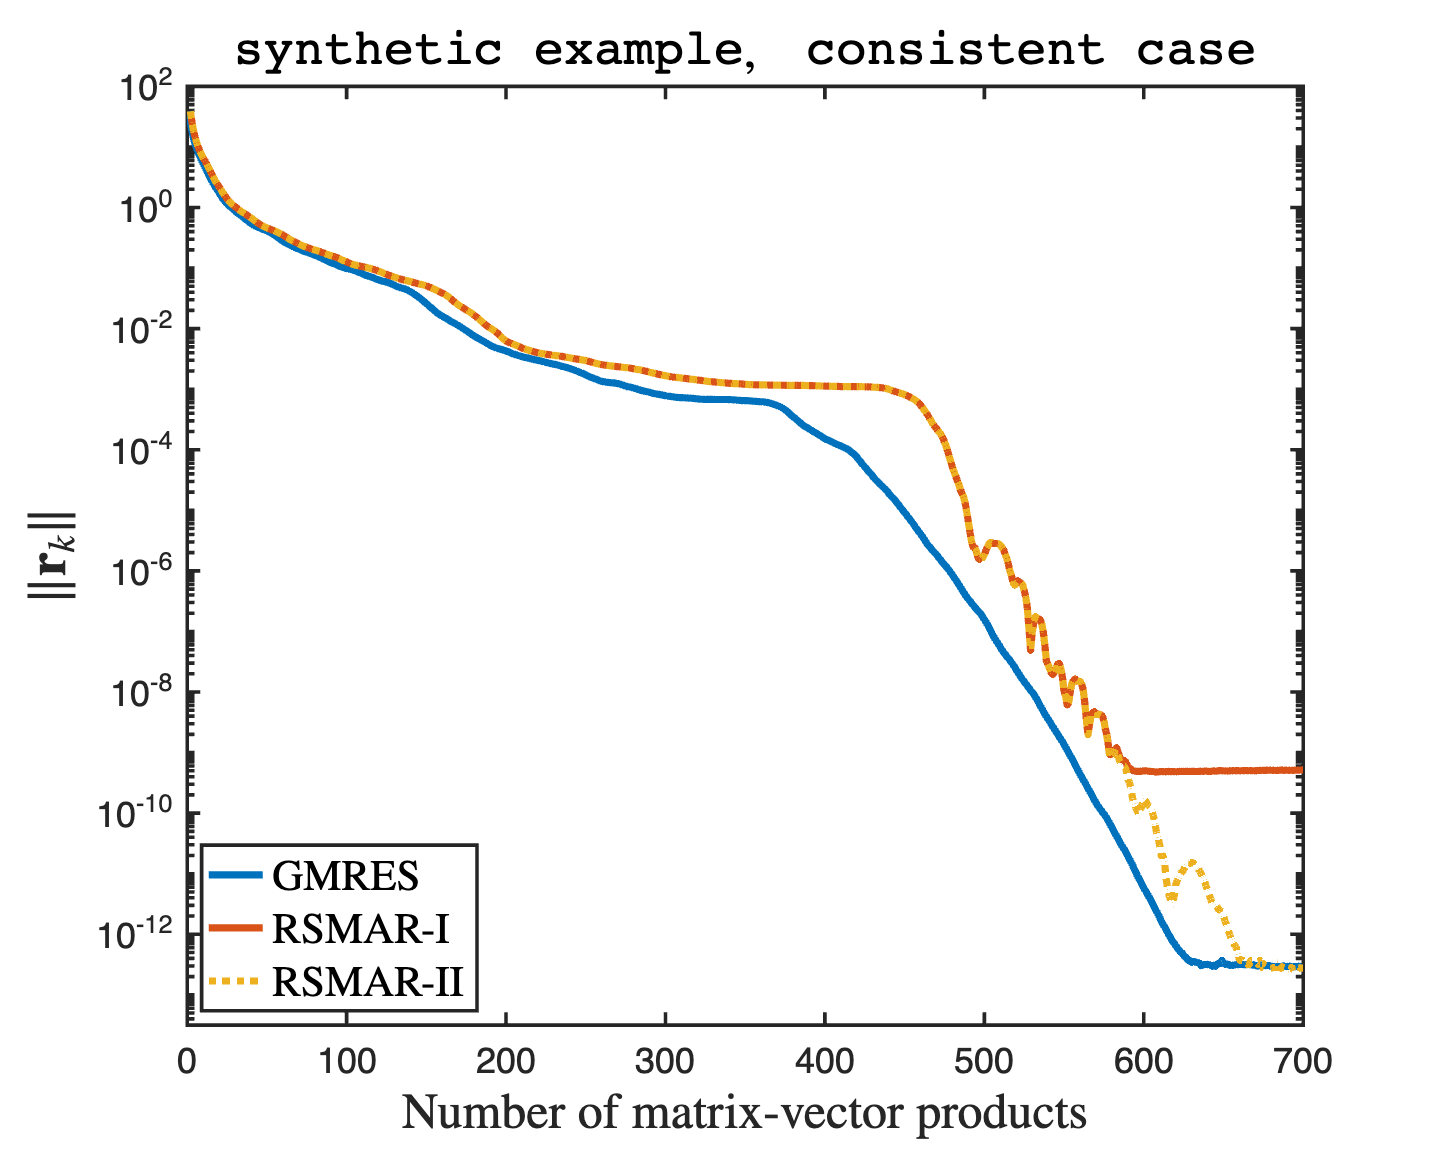

% Kui Du, Jia-Jun Fan, and Fang Wang 2025.04.04
clc; close all; clearvars;
% range symmetric singular consistent system
n = 5000; m = 3000;
rng("default"); U = orth(randn(n));
C = eye(m)+ randn(m)/sqrt(m);
A = U*[C zeros(m,n-m); zeros(n-m,m) zeros(n-m)]*U';
b = A*randn(n,1);
tol = 1e-13; maxit = 700;

[~, ~, gmres_resvec, ~] = gmres(A, b, tol, maxit, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1, criteria=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2, criteria=1);
% [~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit);
% [~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(gmres_resvec), gmres_resvec, LineWidth=4);
hold on;
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
% semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;
xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt synthetic example},\quad{\tt consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES','RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('syn_con','-depsc')

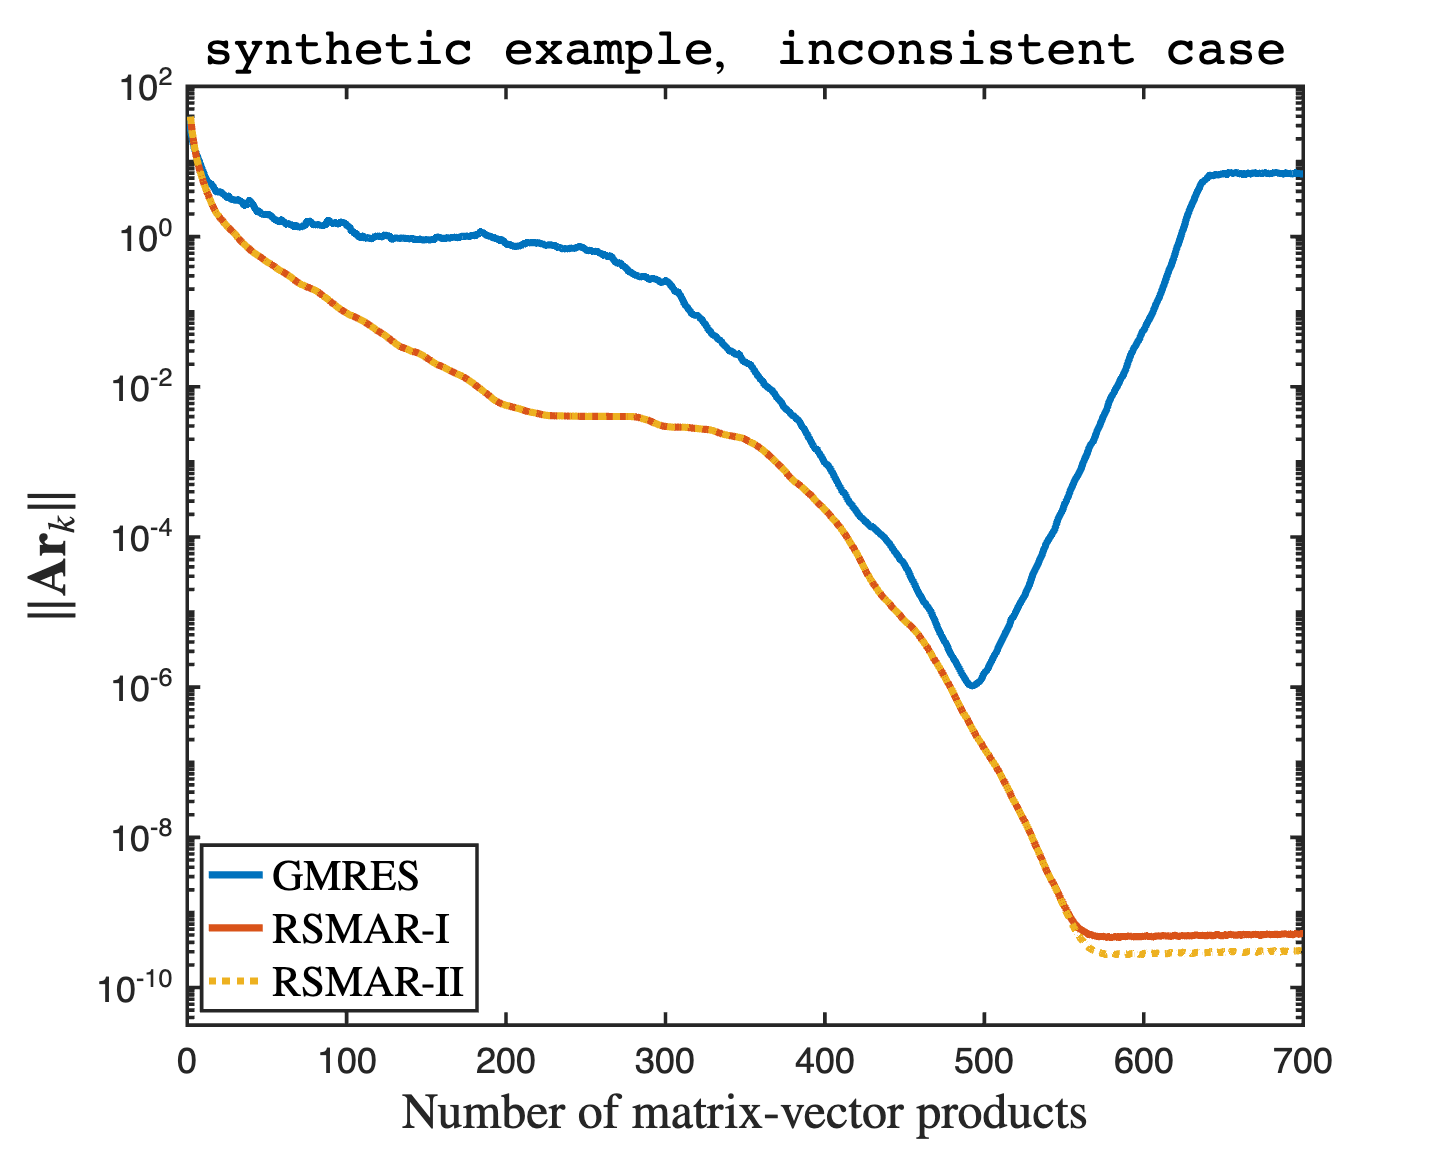

% range symmetric singular inconsistent system
b = randn(n,1);
tol = 1e-10; % maxit = 650;

[~, ~, ~, gmres_Aresvec] = gmres(A, b, tol, maxit, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit, version=2, criteria=2);
% [~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit);
% [~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit);
set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]); 
semilogy(1:length(gmres_Aresvec), gmres_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
% semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");

hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt synthetic example},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('syn_incon','-depsc')

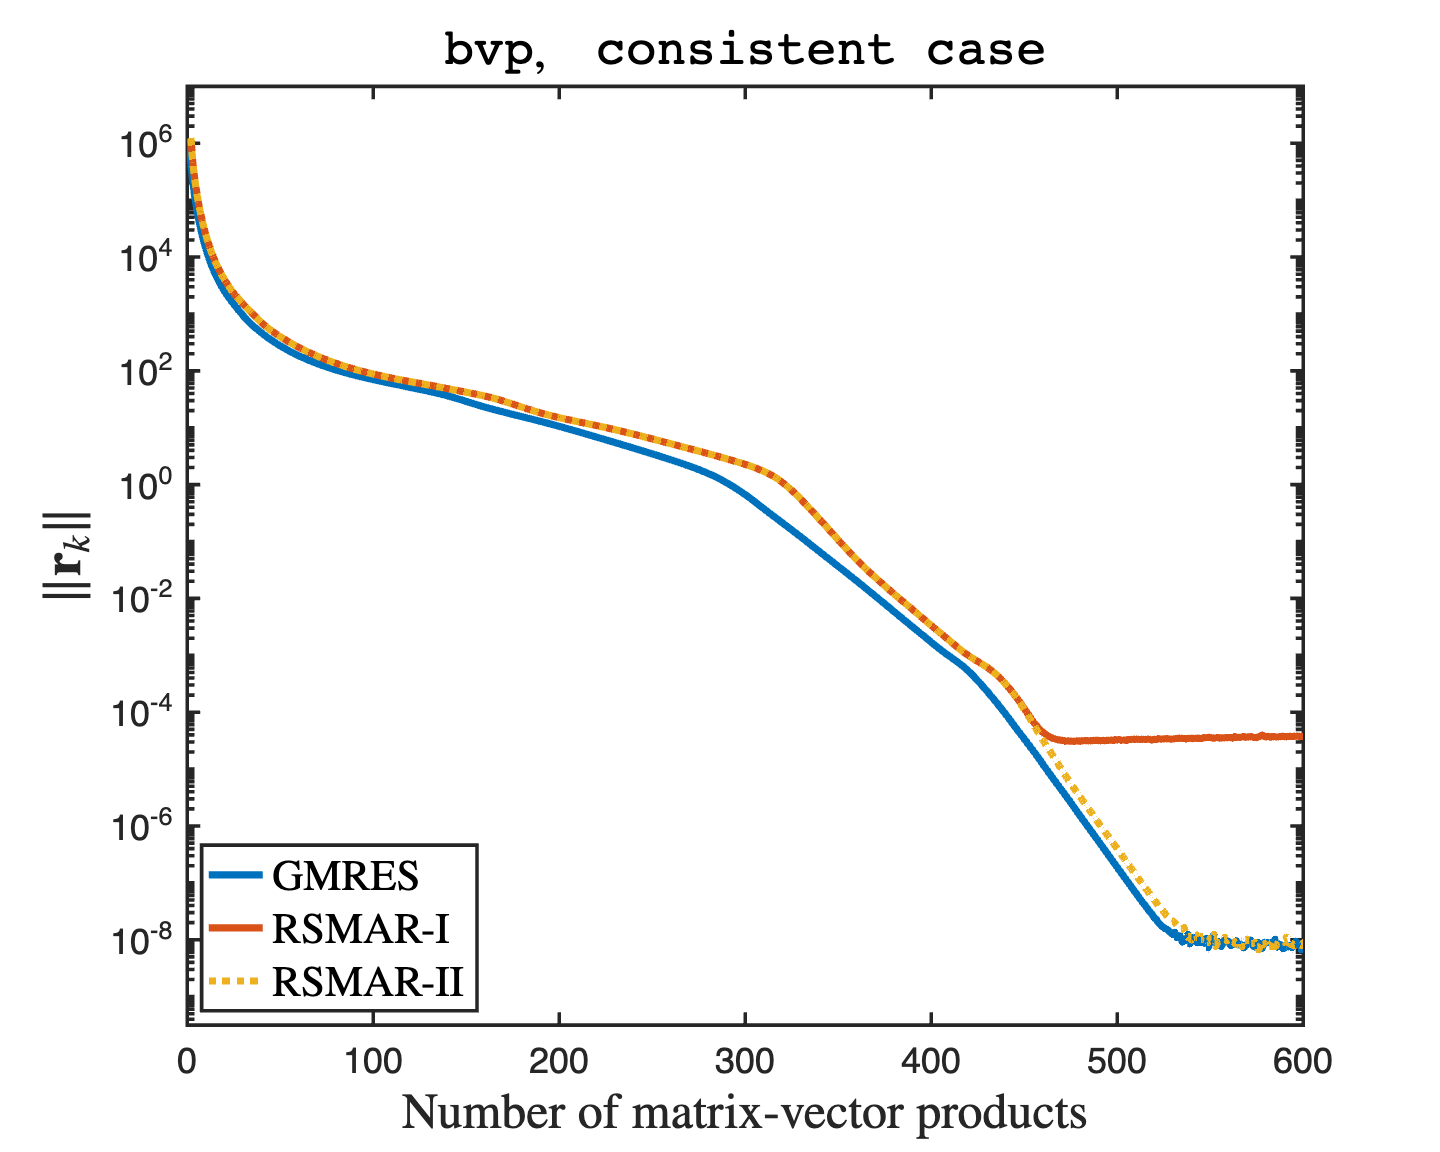

% range symmetric singular consistent system
m = 100; h = 1 / m; d = 10;
a1 = 1 + d * h / 2;
a2 = 1 - d * h / 2;
one = ones(m, 1);
T = spdiags([a2*one, -4*one, a1*one], [-1, 0, 1], m, m);
T(m, 1) = a1; T(1, m) = a2;
A = spdiags([one, one], [-1, 1], m, m);
A(1, m) = 1; A(m, 1) = 1;
A = kron(A, speye(m)) + kron(speye(m), T);
A = A/h/h;

rng("default"); b = A*randn(m*m,1);
tol = 1e-9; maxit = 600;

[~, ~, gmres_resvec, ~] = gmres(A, b, tol, maxit, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1, criteria=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2, criteria=1);
% [~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit);
% [~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(gmres_resvec), gmres_resvec, LineWidth=4);
hold on;
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
% semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;
xlim([0, maxit]), ylim([tol*10^(-0.5) 10^7])
title('{\tt bvp},\quad{\tt consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES','RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('bvp_con','-depsc')

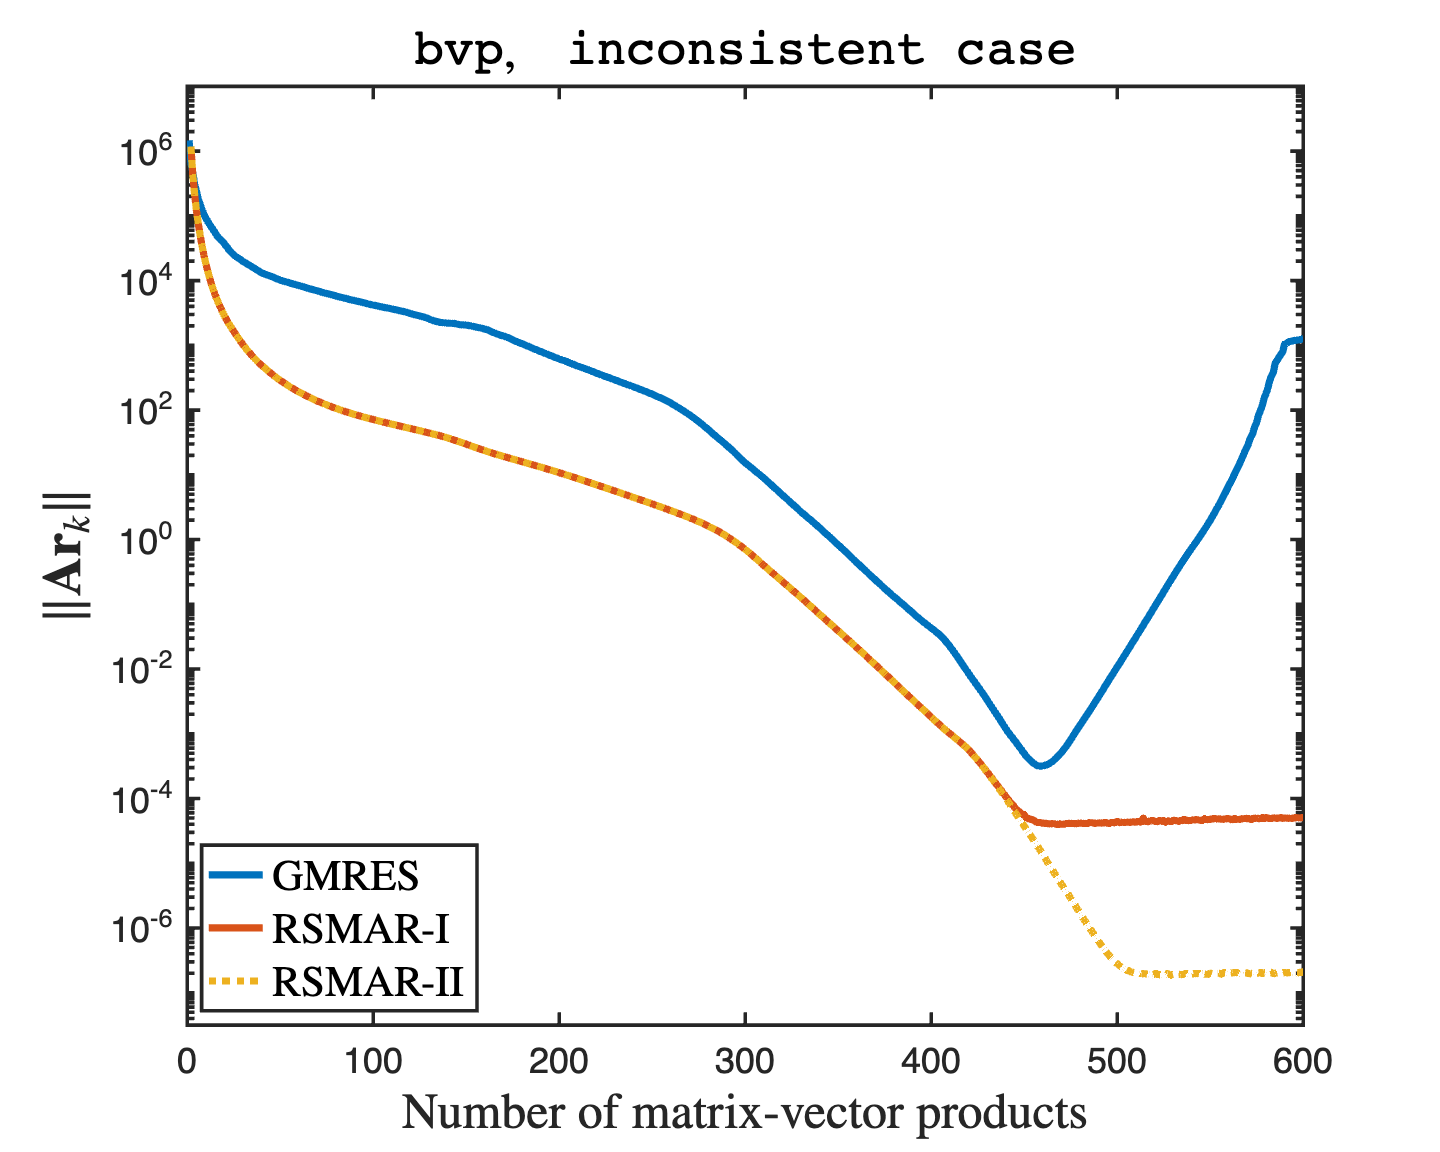

% range symmetric singular inconsistent system
rng("default");  b = randn(m*m,1);
tol = 1e-7; maxit = 600;
[~, ~, ~, gmres_Aresvec] = gmres(A, b, tol, maxit, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit, version=2, criteria=2);
% [~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit);
% [~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit);
set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]); 
semilogy(1:length(gmres_Aresvec), gmres_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
% semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");

hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^7])
title('{\tt bvp},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('bvp_incon','-depsc')

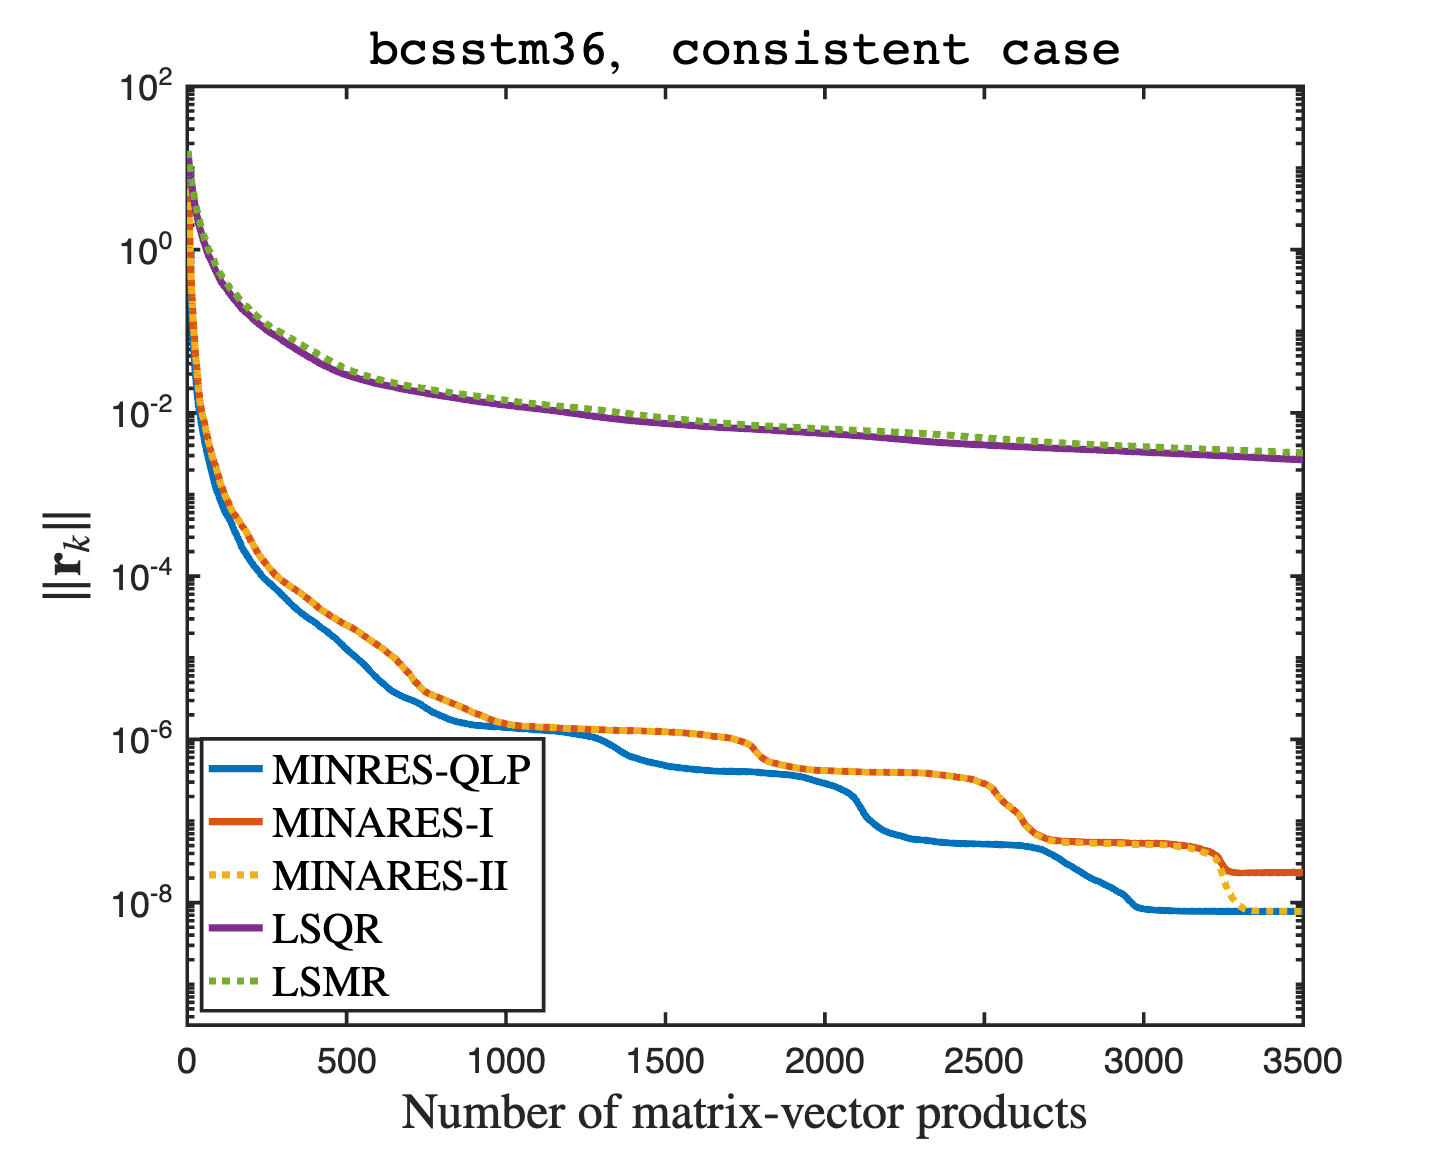

% singular symmetric consistent system

load("matrix/bcsstm36");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-9; maxit = 3500; 
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit/2);
[~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);  
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");


hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt bcsstm36},\quad{\tt consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('bcsstm36_con','-depsc')

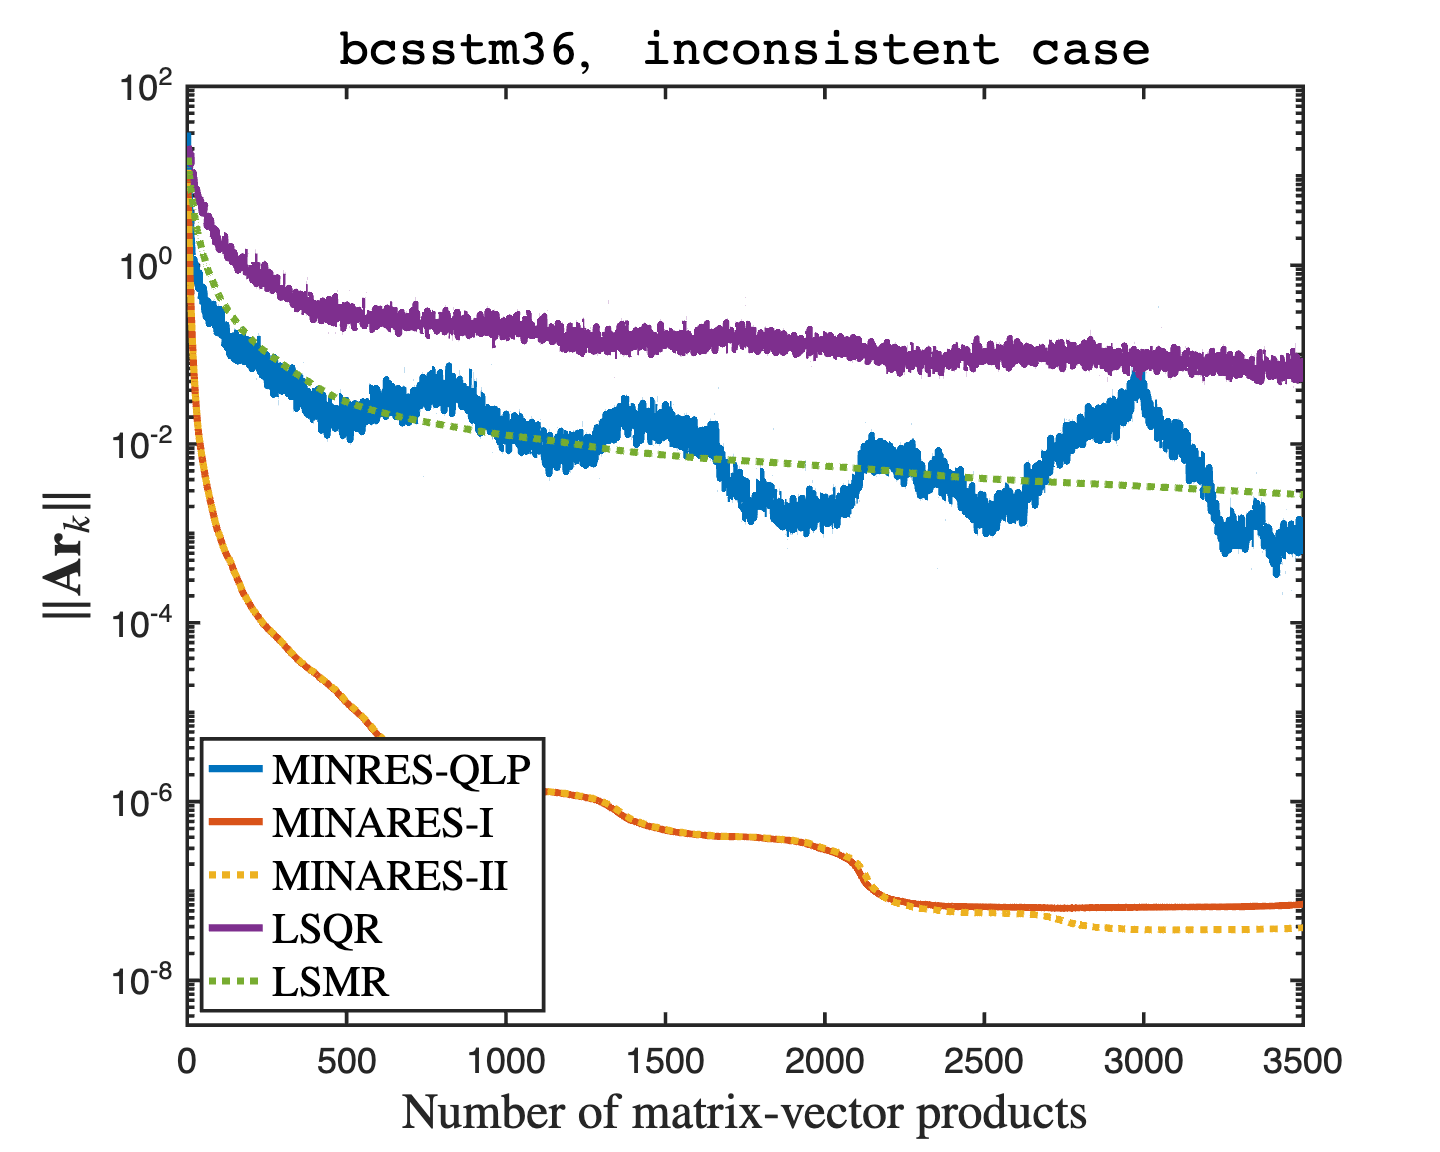

% singular symmetric inconsistent system
b = ones(n, 1);
tol = 1e-8; %maxit = 3000; 
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit/2);
[~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt bcsstm36},\quad{\tt   inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('bcsstm36_incon','-depsc')

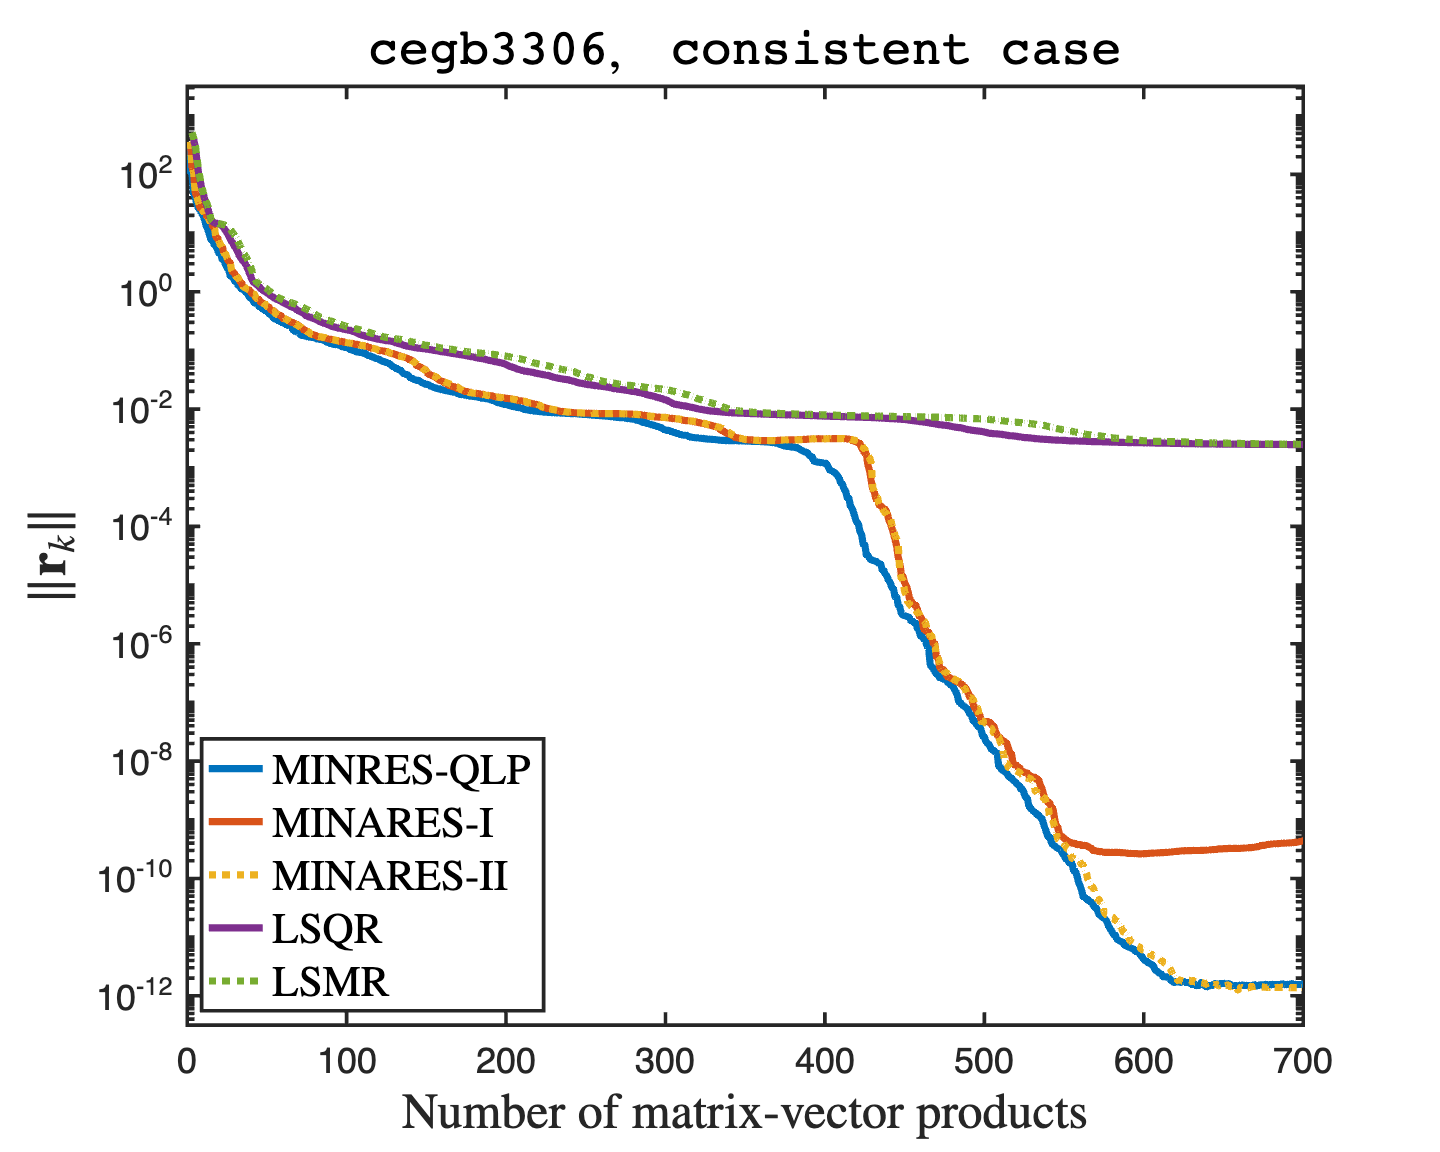

% singular symmetric consistent system
load("matrix/cegb3306");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-12; maxit = 700; 
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit/2);
[~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);  
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^3.5])
title('{\tt cegb3306},\quad{\tt   consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('cegb3306_con','-depsc')

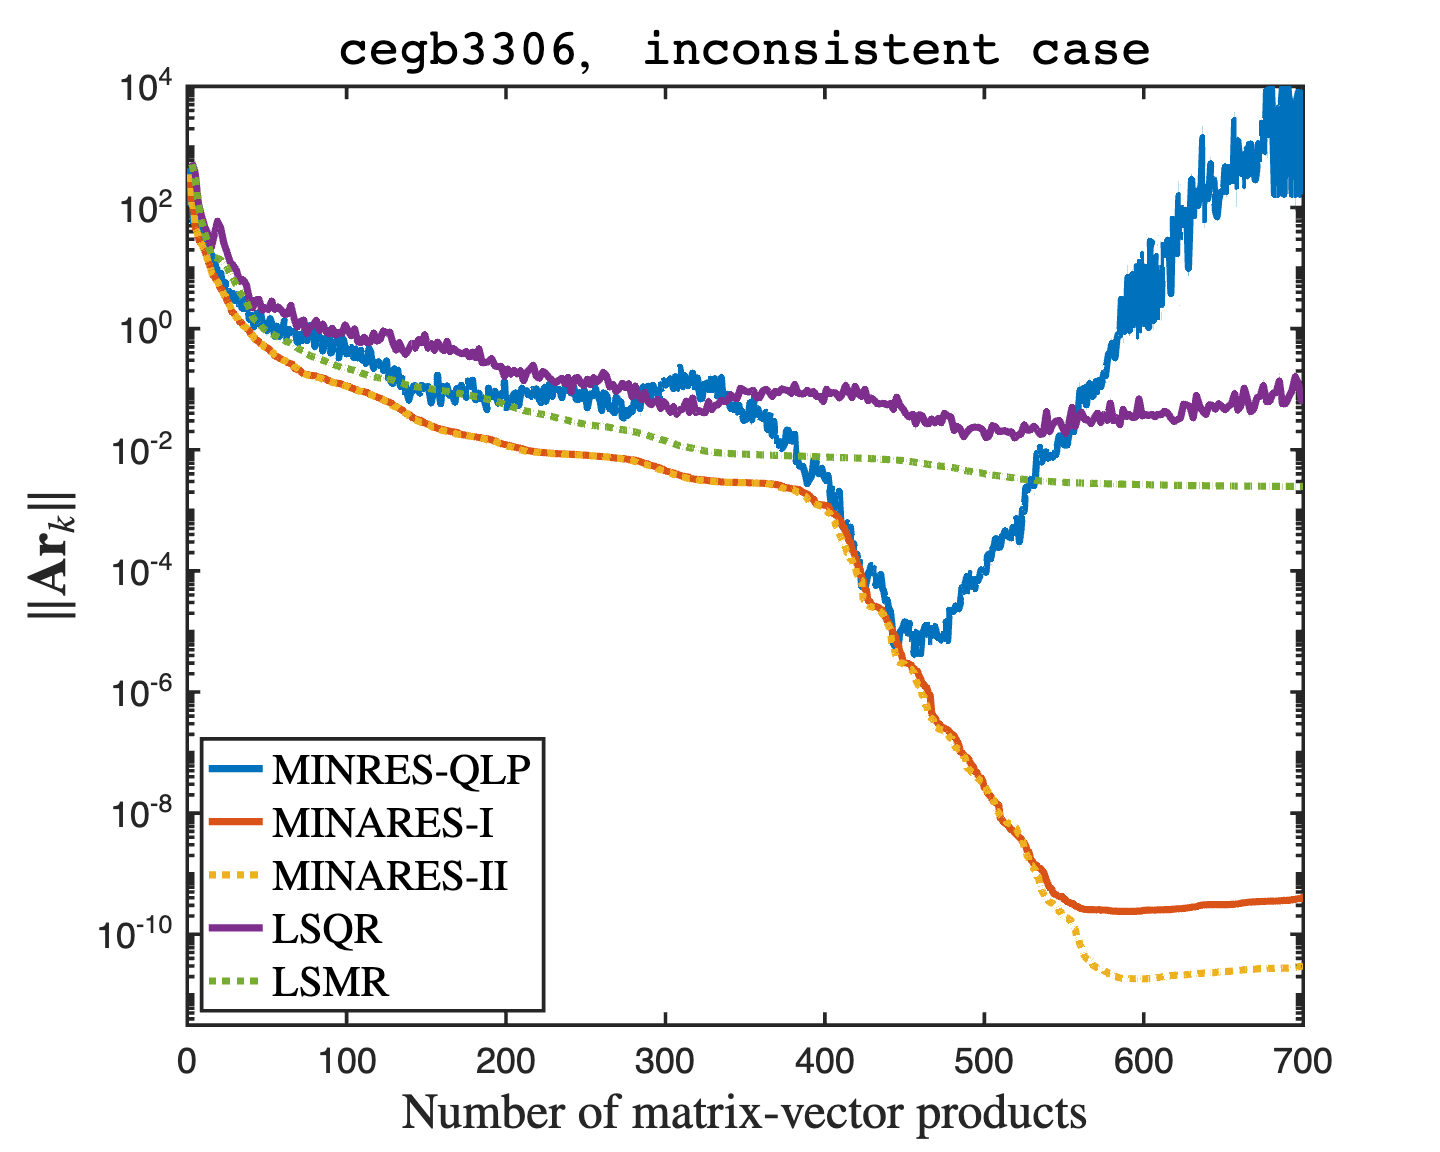

% singular symmetric inconsistent system

b = ones(n, 1);
tol = 1e-12; 
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit/2);
[~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(0.5) 10^4])
title('{\tt cegb3306},\quad{\tt   inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('cegb3306_incon','-depsc')

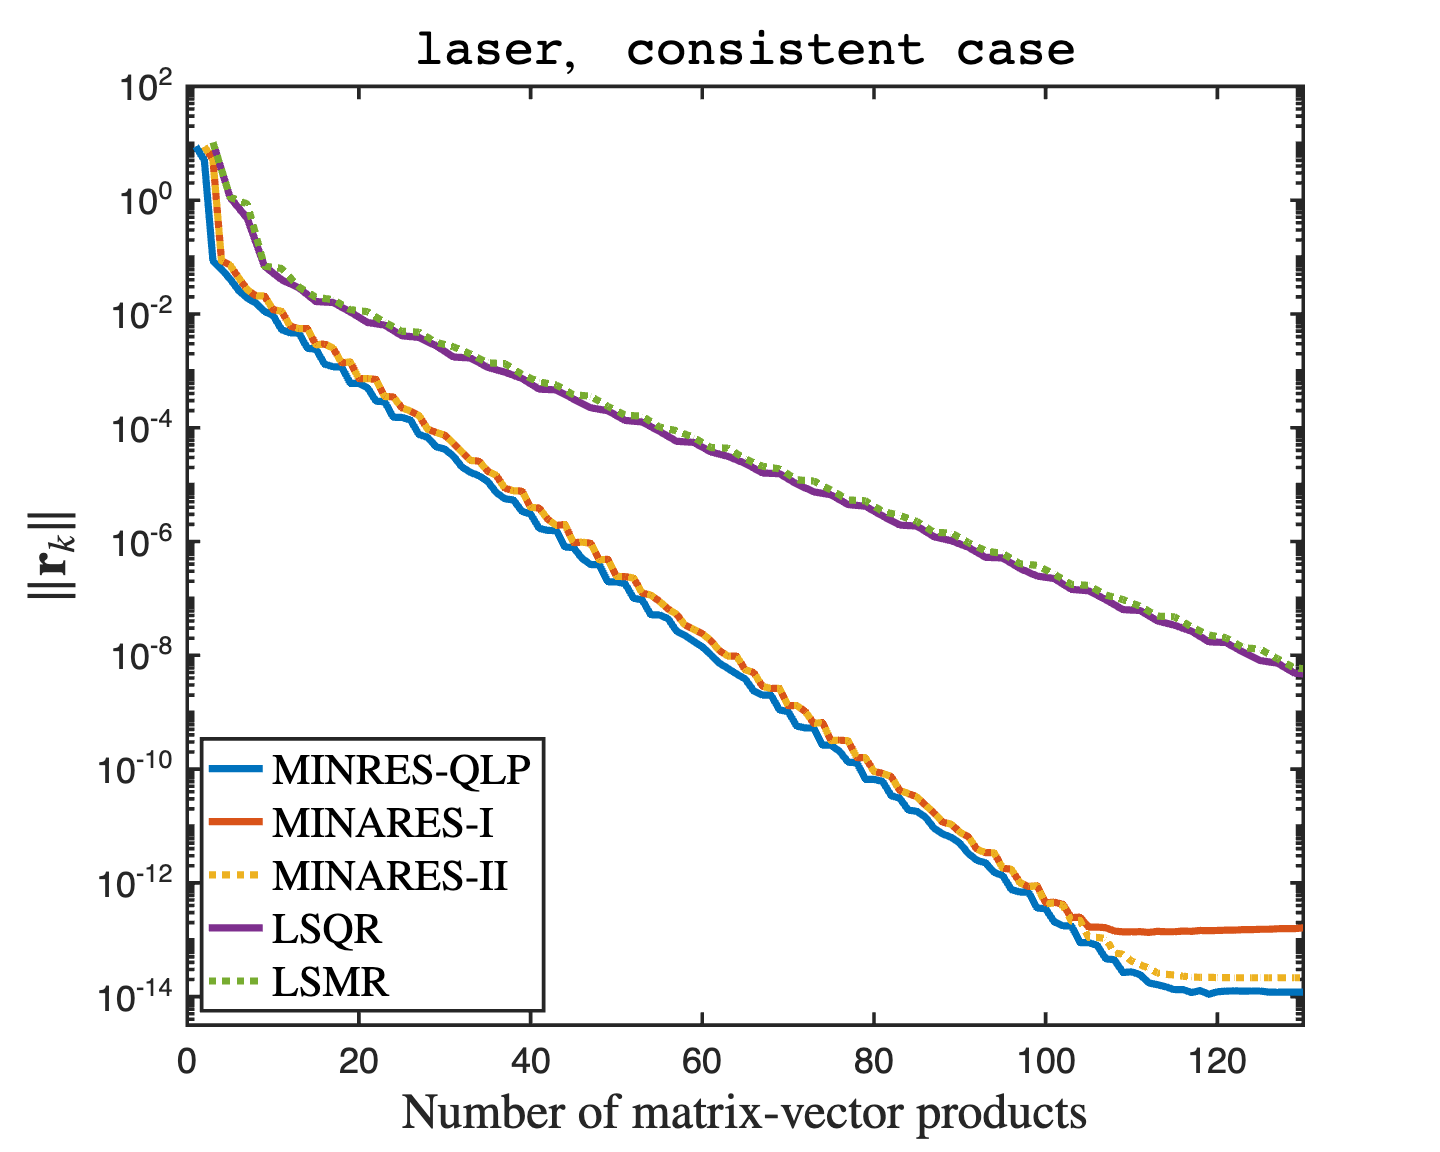

% singular symmetric consistent system
load("matrix/laser");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-14; maxit = 130; 
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit/2);
[~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);  
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt laser},\quad{\tt   consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('laser_con','-depsc')

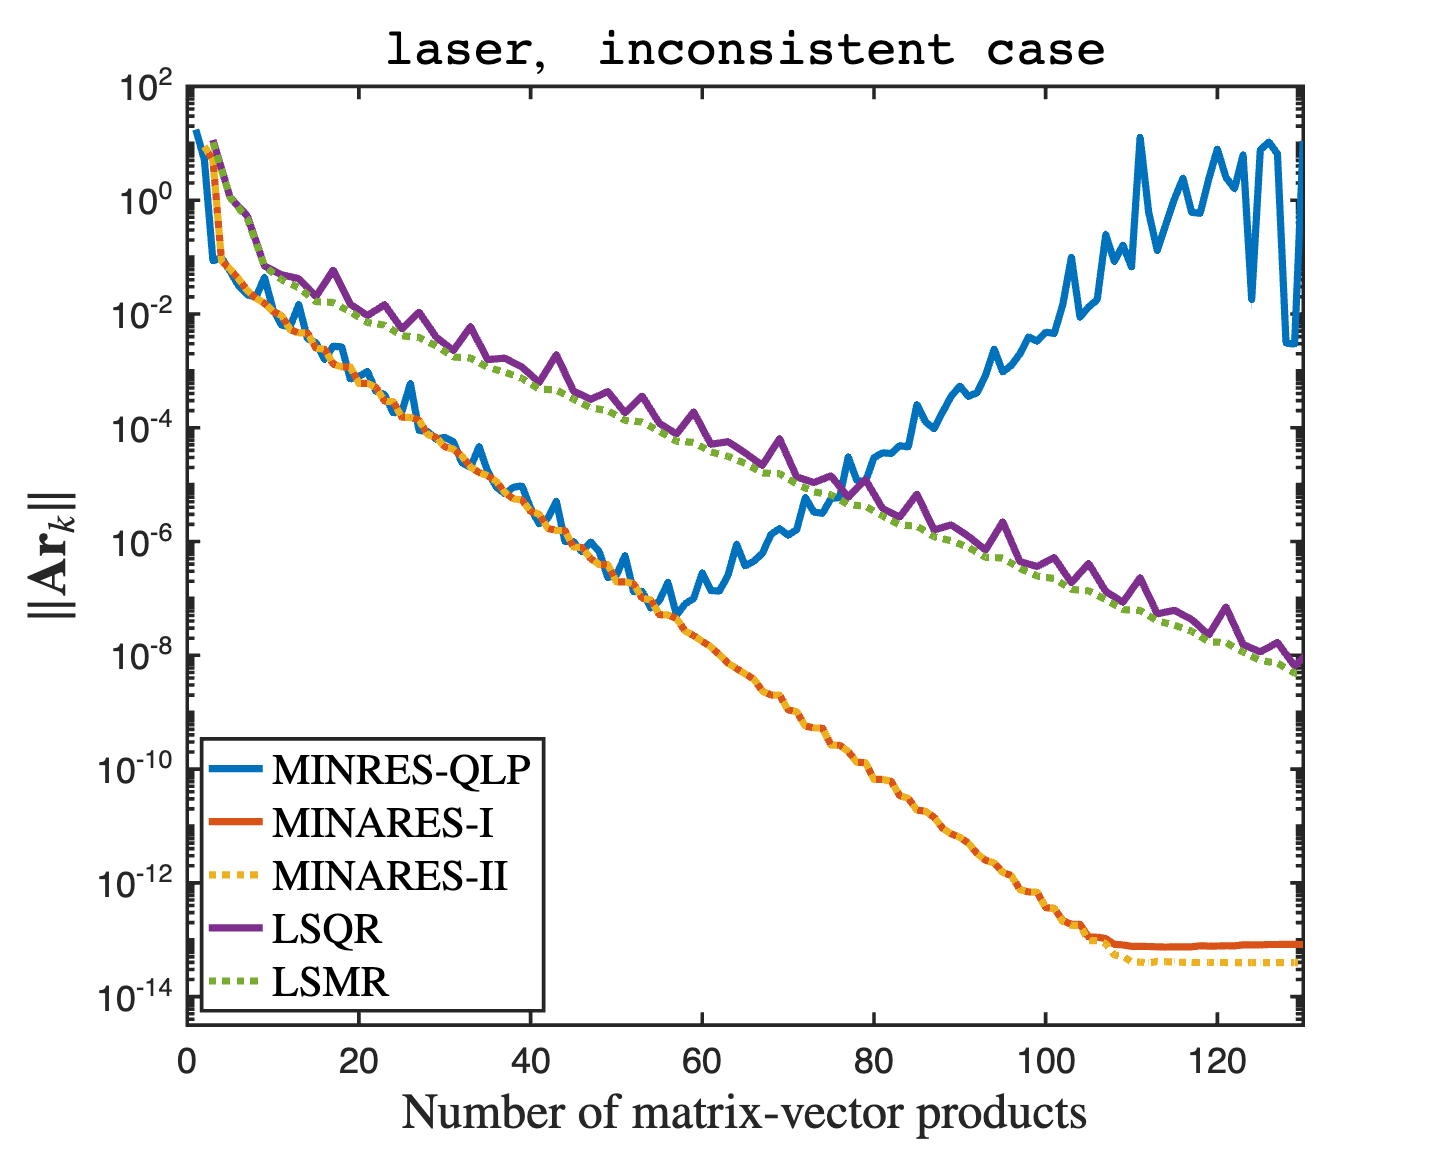

% singular symmetric inconsistent system

b = ones(n, 1);
tol = 1e-14; %maxit = 125; 
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit/2);
[~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit/2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt laser},\quad{\tt   inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'LSQR', 'LSMR'}, Interpreter='latex', FontSize=24, Location='SW');
print('laser_incon','-depsc')